## Load

%clear;
%load('pcloud');


## Show original point cloud.

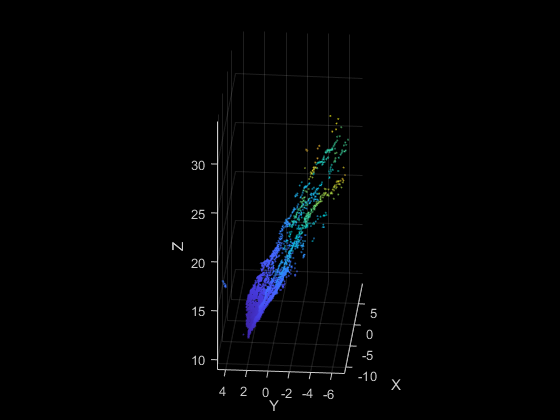

p=pointCloud(xyzPoints);
figure; pcshow(p);
xlabel("X");ylabel("Y");zlabel("Z");

## Rotate point cloud to match level terrain

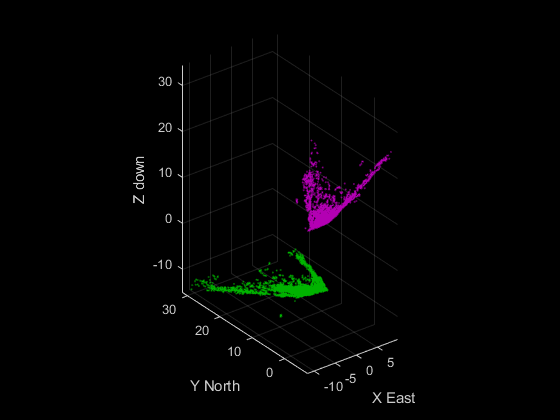

% rotate over X
a=55;
ang=deg2rad(-a-180); % -60 works best (-90-pitch)
tform= affine3d(axang2tform([1 0 0 ang]));
plevel = pctransform(p,tform); % magenta 1 green 2
figure;
pcshowpair(p,plevel);
xlabel("X East");ylabel("Y North");zlabel("Z down");

## Rotate to account for heading

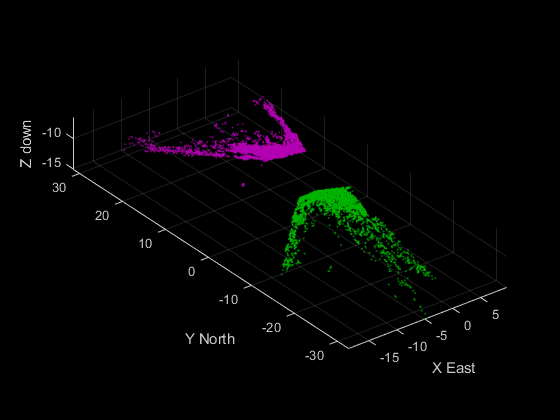

% rotate over Z
ang=deg2rad(-heading(1)); 
tform= affine3d(axang2tform([0 0 1 ang]));
pheaded = pctransform(plevel,tform); % magenta 1 green 2
figure;
pcshowpair(plevel,pheaded);
xlabel("X East");ylabel("Y North");zlabel("Z down");

## Scale point cloud

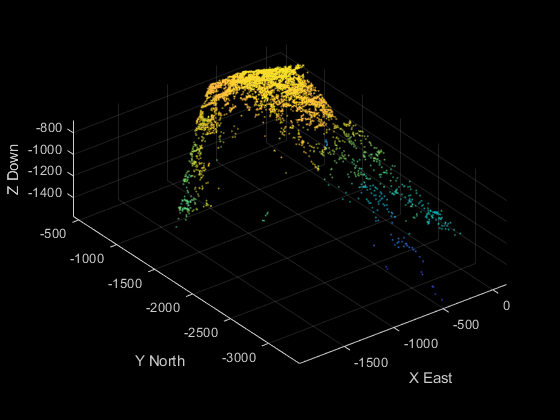

% get camera poses from gps
origin = [gps(1,1), gps(1,2), altitude(1)];
[cam_x,cam_y] = latlon2local(gps(:,1),gps(:,2),altitude,origin);
cam_z=-altitude;

% get estimated camera poses
cams=zeros(size(camPoses,1),3);
for i=1:size(camPoses,1)
    cams(i,:)=camPoses.AbsolutePose(i).Translation;
end

% scale using the distance bewteen the first and final point
D=sqrt(cam_x(end)^2+cam_y(end)^2+(cam_z(end)-cam_z(1))^2);
D_est=sqrt(cams(end,1)^2 + cams(end,2)^2 + cams(end,3)^2);
s=D/D_est;

% apply transform
tform = affine3d([s 0 0 0; 0 s 0 0; 0 0 s 0; 0 0 0 1]);
pscaled=pctransform(pheaded,tform);

% show new point cloud
figure; pcshow(pscaled);
xlabel("X East");ylabel("Y North");zlabel('Z Down');

## Sum altitude

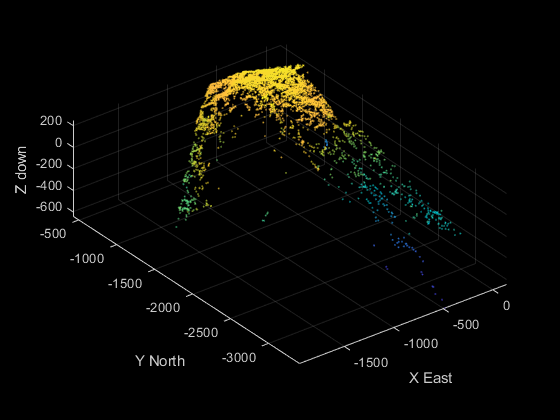

tform=affine3d([eye(3,4);[0 0 altitude(1) 1]]);
pf=pctransform(pscaled,tform);
figure;
pcshow(pf);
xlabel("X East");ylabel("Y North");zlabel("Z down");

## Show 3d results

Terrain height at x=39.844470 y=-8.542760 :
 286.910858 m


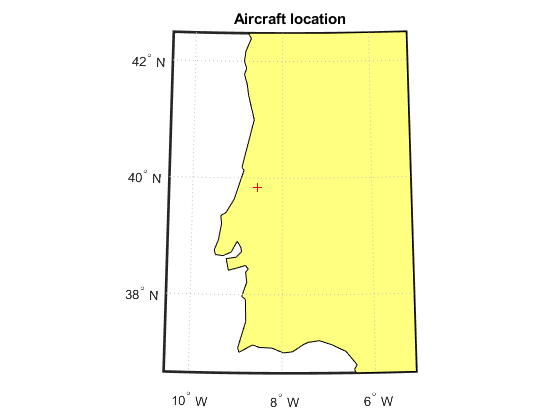

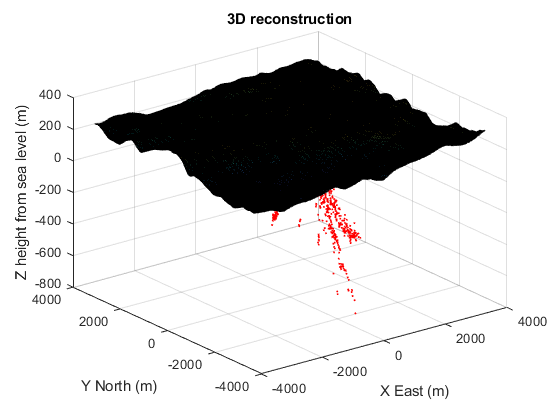

if exist('A','var') == 0
    load("DEMs/portugal_DEM");
end 
show3Dresults(A,R,pf.Location,[0 0 0],gps);

## Manipulate final point cloud

Terrain height at x=39.844470 y=-8.542760 :
 286.910858 m


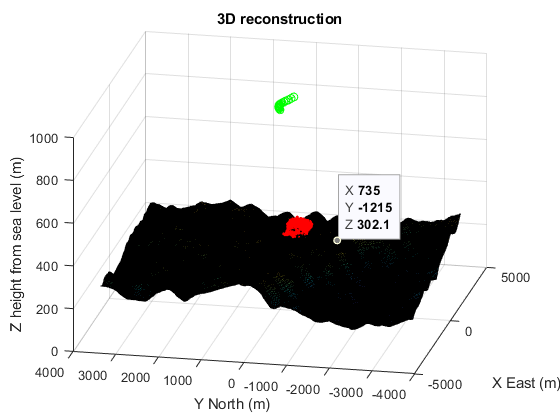

% show 3d result
if exist('A','var') == 0
    load("DEMs/portugal_DEM");
end
show3Dresults(A,R,pfilt,traj,gps);

% height histogram
